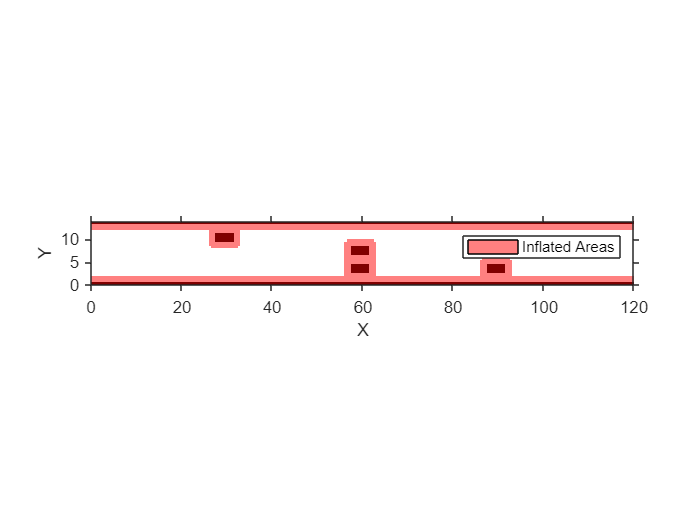

map = binaryOccupancyMap(120, 14, 2);
occ = zeros(28, 240);
occ([1,28],:) = 1;
occ(6:9,[56:63]) = 1;
occ(12:15,[116:123]) = 1;
occ(20:23,[116:123]) = 1;
occ(20:23,[176:183]) = 1;
setOccupancy(map, occ)
res = 0.5; % meters
costmap = vehicleCostmap(map, 'CellSize', res);
figure
vehicleDims = vehicleDimensions;

numCircles = 3;
ccConfig = inflationCollisionChecker(vehicleDims,numCircles);
costmap.CollisionChecker = ccConfig;
plot(costmap)

poses = [1 10 0;33 7 0; 63 10 0; 93 7 0; 117 4 0];

vMap = validatorVehicleCostmap;
vMap.Map = costmap;

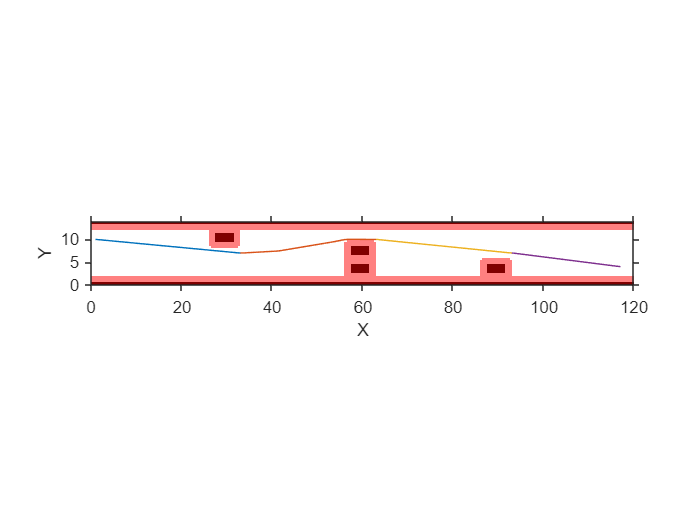

planner = plannerCustomized(vMap,'MinTurningRadius',3, "NumMotionPrimitives", 7);

plot(vMap.Map)
hold on
for i=1:(size(poses,1)-1)
    path = plan(planner, poses(i, :), poses(i+1, :));
    [transitionPoses, ~] = interpolate(path);

    plot(transitionPoses(:,1),transitionPoses(:,2));
    legend off;
end
hold off;

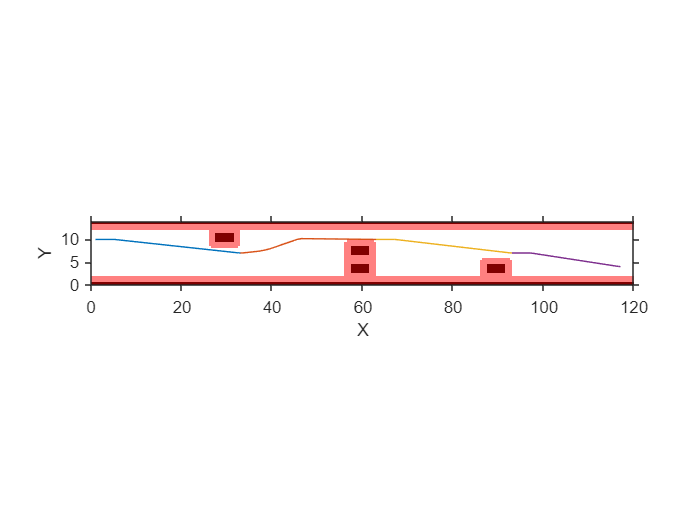

planner = plannerHybridAStar(vMap,'MinTurningRadius',3, "NumMotionPrimitives", 7);

plot(vMap.Map)
hold on
for i=1:(size(poses,1)-1)
    route = plan(planner, poses(i, :), poses(i+1, :));
    pathPoses = route.States;

    % Convert theta back to degrees
    pathPoses(:,3) = rad2deg(pathPoses(:,3));

    % Create a Dubins connection object
    conn = driving.internal.planning.DubinsConnection.create();
    conn.MinTurningRadius = planner.MinTurningRadius;

    % Create an array of Dubins path segments
    pathSeg = driving.DubinsPathSegment.makeempty();
    for n = 1 : size(pathPoses,1)-1
        pathSeg(n) = driving.DubinsPathSegment.create(...
            conn, pathPoses(n,:), pathPoses(n+1,:));
    end

    pathObj = driving.Path.create(pathSeg);
    [transitionPoses, ~] = interpolate(pathObj);
    plot(transitionPoses(:,1),transitionPoses(:,2));
    legend off;
end
hold off;

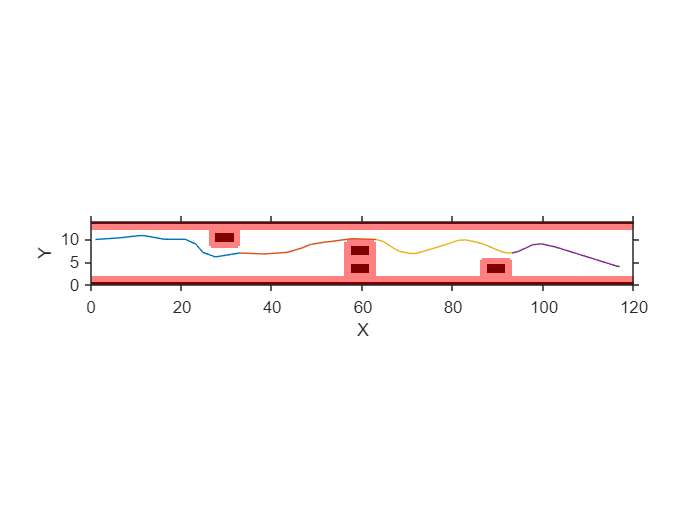

planner = pathPlannerRRT(vMap.Map,'MinTurningRadius',3,'MinIterations',1);

plot(vMap.Map)
hold on
for i=1:(size(poses,1)-1)
    path = plan(planner, poses(i, :), poses(i+1, :));
    [transitionPoses, ~] = interpolate(path);

    plot(transitionPoses(:,1),transitionPoses(:,2));
    legend off;
end
hold off;